# Global Thresholding for everyone

## Load the data

Load the transcriptomics data, the housekeeping genes obtained in the previous script, and the metabolic model (Human1 version).

% Transcriptomics data
data = readtable('Mod_data.xlsx');
% Housekeeping genes with the ensembl ids
h_k_g = readtable('NM2ENSG.xlsx')

h_k_g = 3804×5 table
    initial_alias      converted_alias         name                                                   description                                                     namespace     
    _____________    ___________________    ___________    __________________________________________________________________________________________________    ___________________

    {'NM_003859'}    {'ENSG00000000419'}    {'DPM1'   }    {'dolichyl-phosphate mannosyltransferase subunit 1, catalytic [Source:HGNC Symbol;Acc:HGNC:3005]'}    {'REFSEQ_MRNA_ACC'}
    {'NM_020423'}    {'ENSG00000000457'}    {'SCYL3'  }    {'SCY1 like pseudokinase 3 [Source:HGNC Symbol;Acc:HGNC:19285]'                                  }    {'REFSEQ_MRNA_ACC'}
    {'NM_001498'}    {'ENSG00000001084'}    {'GCLC'   }    {'glutamate-cysteine liga

% h_k_g = readtable('housekeeping_ens.csv')
h_k_g = h_k_g.converted_alias
% Human1 metabolic model.
%model = load('Human-GEM_Cobra_v1.01.mat')
%model = load('SysBio_COBRA_v1.13.mat')
%model = model.model
model = load('SysBio_COBRA_v1.17_consensus.mat')

model = struct with fields:
    myModel: [1×1 struct]


model = model.myModel;

## Metabolic genes

### Pick the genes related to metabolism

In the transcriptomics dataset there are a lot of genes, but we are interested just in those ones that take part in the metabolism, so, we are going to compare the ensembl id of both, the transcriptomics dataset and the Human1 metabolic model, and pick those ones that are present.

% Create a vector just with the ensembl ids of the genes from the model
model_genes = model.genes;
% Find indexes of the genes that are present in the metabolic model. 
index_names = ismember(data.Ensembl_GeneID, model_genes);
% take the rows of the dataset that match the indexes obtained before, with all the data 
data_met = data(index_names, :);

## For loop to calculate the accuracy for all the samples

% Initialise a table to store the results
results = table;
% Get expression data column names
expression_col = data_met.Properties.VariableNames(2:end);
results_colname = []


results_colname =

     []



results_percentage_hk = []


results_percentage_hk =

     []



now create the for loop where a threshold will be established based on the 70th percentile of gene expression for each sample, with genes above this threshold being considered core genes. Moreover, the accuracy will also be calculated on the basis of the housekeeping genes expressed as core genes divided by those related to metabolism. 

% Iterate over each column of expression data
for i = 1:length(expression_col)
    % Select the expression data column
    col_name = expression_col{i};
    expfibroblast = data_met(:,1); 
    expfibroblast(:,2) = data_met(:, col_name); 
    expfibroblast.Properties.VariableNames{1} = 'gene';
    expfibroblast.Properties.VariableNames{2} = 'FPKMvalue';

    % Perform the calculations
    expfibroblast.logFPKMvalue = log10(expfibroblast{:,2} + 1); 
    expfibroblast.value = expfibroblast.logFPKMvalue - min(expfibroblast.logFPKMvalue); 

    % Calculate the threshold, creating a slider form 70 to 100
    percentage =70;
    up_threshold_fib = prctile(expfibroblast.value, percentage);

    % Filtering the data
    idx = expfibroblast.value >= up_threshold_fib;
    filtered_data = expfibroblast(idx, :);

    % Select the ensembl id of the core genes
    genes_table = data_met.Ensembl_GeneID;
    
    %% housekeeping
    % See how many housekeeping genes in the list have metabolic functions. 
    index_names = ismember(genes_table, h_k_g.converted_alias);
    hkg_met = data_met(index_names, :);

    % Now just the ensmbl id
    hkg_met_ens = hkg_met(:, "Ensembl_GeneID");

    % Finding the housekeeping genes among the filtered genes
    ens_filt_dat = filtered_data.gene;
    matching_names_idx = ismember(ens_filt_dat, hkg_met_ens.Ensembl_GeneID);
    matching_names = filtered_data(matching_names_idx, 1);

    % Calculate the percentage of maintenance genes
    percentage_hk = (length(matching_names.gene) / length(ens_filt_dat)) * 100;

    % Save the results in the table
    results{i, 'Column'} = {col_name};
    results{i, 'PorcentageHK'} = percentage_hk;
end

results_FPKM = results

results_FPKM = 48×2 table
       Column       PorcentageHK
    ____________    ____________

    {'BJ_Y1'   }       49.417   
    {'BJ_Y2'   }       49.184   
    {'BJ_Y3'   }       48.834   
    {'BJ_OLD_1'}       48.485   
    {'BJ_OLD_2'}       48.485   
    {'BJ_OLD_3'}       48.368   
    {'IMR90_Y1'}       50.583   
    {'IMR90_Y2'}       51.049   
    {'IMR90_Y3'}       50.699   
    {'IMR90_O1'}       50.583   
    {'IMR90_O2'}       49.767   
    {'IMR90_O3'}       49.767   
    {'WI_38_Y1'}       51.049   
    {'WI_38_Y2'}       51.399   
    {'WI_38_Y3'}       50.932   
    {'WI_38_O1'}       49.417   


% Show results
disp(results_FPKM);

         Column         PorcentageHK
    ________________    ____________

    {'BJ_Y1'       }       49.417   
    {'BJ_Y2'       }       49.184   
    {'BJ_Y3'       }       48.834   
    {'BJ_OLD_1'    }       48.485   
    {'BJ_OLD_2'    }       48.485   
    {'BJ_OLD_3'    }       48.368   
    {'IMR90_Y1'    }       50.583   
    {'IMR90_Y2'    }       51.049   
    {'IMR90_Y3'    }       50.699   
    {'IMR90_O1'    }       50.583   
    {'IMR90_O2'    }       49.767   
    {'IMR90_O3'    }       49.767   
    {'WI_38_Y1'    }       51.049   
    {'WI_38_Y2'    }       51.399   
    {'WI_38_Y3'    }       50.932   
    {'WI_38_O1'    }       49.417   
    {'WI_38_O2'    }       49.184   
    {'WI_38_O3'    }        49.65   
    {'HFF_PD16_1'  }       49.883   
    {'HFF_PD16_2'  }       50.233   
    {'HFF_PD16_3'  }           50   
    {'HFF_PD74_1'  }       47.902   
    {'HFF_PD74_2'  }       47.902   
    {'

The results are shown according to the different samples, but we can see that the values are around 60%, which is not bad data, but we expected better.

Save the results table in a csv file

% Save as CSV
writetable(results_FPKM, 'results.csv');

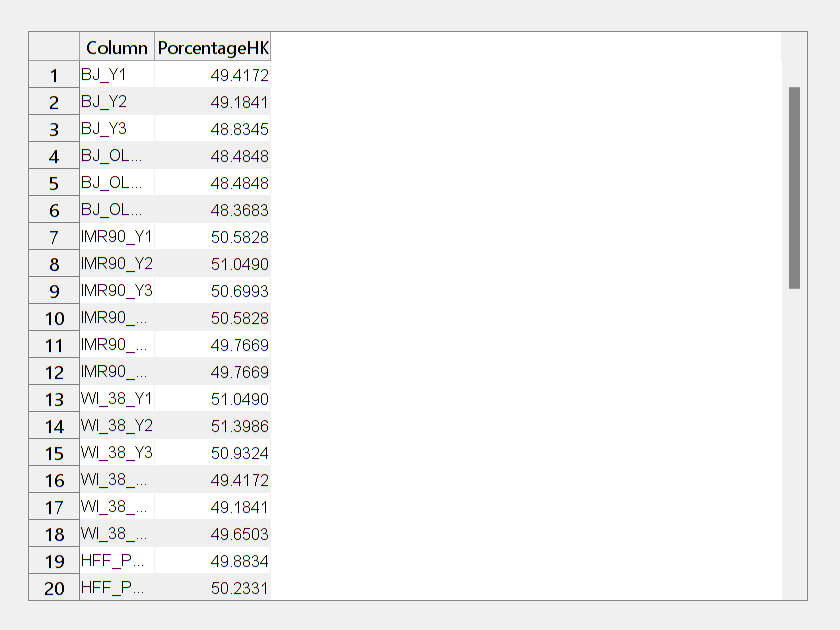

% Create a table with the results
f = figure('Name', 'Results', 'NumberTitle', 'off');
t = uitable(f, 'Data', table2cell(results), 'ColumnName', results_FPKM.Properties.VariableNames);
t.Position = [20 20 f.Position(3)-40 f.Position(4)-40];

# With TPM

%clear all;
%close all;

## Load the data again

Load the transcriptomics data, the housekeeping genes obtained in the previous script, and the metabolic model (Human1 version).

% Transcriptomics data
data = readtable('Mod_data.xlsx');
% Housekeeping genes with the ensembl ids
h_k_g = readtable('NM2ENSG.xlsx')

h_k_g = 3804×5 table
    initial_alias      converted_alias         name                                                   description                                                     namespace     
    _____________    ___________________    ___________    __________________________________________________________________________________________________    ___________________

    {'NM_003859'}    {'ENSG00000000419'}    {'DPM1'   }    {'dolichyl-phosphate mannosyltransferase subunit 1, catalytic [Source:HGNC Symbol;Acc:HGNC:3005]'}    {'REFSEQ_MRNA_ACC'}
    {'NM_020423'}    {'ENSG00000000457'}    {'SCYL3'  }    {'SCY1 like pseudokinase 3 [Source:HGNC Symbol;Acc:HGNC:19285]'                                  }    {'REFSEQ_MRNA_ACC'}
    {'NM_001498'}    {'ENSG00000001084'}    {'GCLC'   }    {'glutamate-cysteine liga

% h_k_g = readtable('housekeeping_ens.csv');
% Human1 metabolic model.
%model = load('Human-GEM_Cobra_v1.01.mat');
% model = load('SysBio_COBRA_v1.13.mat')
model = load('SysBio_COBRA_v1.17_consensus.mat')

model = struct with fields:
    myModel: [1×1 struct]


model = model.model;

Unrecognized field name "model".

# Convert the data from FPKM to TPM

It was decided to explore new alternatives for the normalisation of gene expression data by switching from FPKM (Fragments Per Kilobase Million) to TPM (Transcripts Per Million), which has been shown in other studies to facilitate comparison between different samples.

% Extract matrix from table
data_matrix = data{:, 2:end};

% Calculate the sum of each column
column_sums = sum(data_matrix, 1);

% Normalize each element by the sum of its column and then multiply by 10^6
normalized_matrix = (data_matrix ./ column_sums) * 1e6;

% Convert the normalized matrix back to a table
normalized_table = array2table(normalized_matrix, 'VariableNames', data.Properties.VariableNames(2:end));

% Replace the relevant columns in the original table
data(:, 2:end) = normalized_table;
data

## Metabolic genes

### Pick the genes related to metabolism

In the transcriptomics dataset there are a lot of genes, but we are interested just in those ones that take part in the metabolism, so, we are going to compare the ensembl id of both, the transcriptomics dataset and the Human1 metabolic model, and pick those ones that are present.

% Create a vector just with the ensembl ids of the genes from the model
model_genes = model.genes;
% Find indexes of the genes that are present in the metabolic model. 
index_names = ismember(data.Ensembl_GeneID, model_genes);
% take the rows of the dataset that match the indexes obtained before, with all the data 
data_met = data(index_names, :);

## For loop to calculate the percentage of all the samples

% Initialise a table to store the results
results = table;
% Get expression data column names
expression_col = data_met.Properties.VariableNames(2:end);
results_colname = []
results_percentage_hk = []

now create the for loop where a threshold will be established based on the 70th percentile of gene expression for each sample, with genes above this threshold being considered core genes. Moreover, the accuracy will also be calculated on the basis of the housekeeping genes expressed as core genes divided by those related to metabolism. 

% Iterate over each column of expression data
for i = 1:length(expression_col)
    % Select the expression data column
    col_name = expression_col{i};
    expfibroblast = data_met(:,1); 
    expfibroblast(:,2) = data_met(:, col_name); 
    expfibroblast.Properties.VariableNames{1} = 'gene';
    expfibroblast.Properties.VariableNames{2} = 'FPKMvalue';

    % Perform the calculations
    expfibroblast.logFPKMvalue = log10(expfibroblast{:,2} + 1); 
    expfibroblast.value = expfibroblast.logFPKMvalue - min(expfibroblast.logFPKMvalue); 

    % Calculate the threshold, creating a slider form 70 to 100
    percentage =70;
    up_threshold_fib = prctile(expfibroblast.value, percentage);

    % Filtering the data
    idx = expfibroblast.value >= up_threshold_fib;
    filtered_data = expfibroblast(idx, :);

    % Select the ensembl id of the core genes
    genes_table = data_met.Ensembl_GeneID;
    
    %% housekeeping
    % See how many housekeeping genes in the list have metabolic functions. 
    index_names = ismember(genes_table, h_k_g.converted_alias);
    hkg_met = data_met(index_names, :);

    % Now just the ensmbl id
    hkg_met_ens = hkg_met(:, "Ensembl_GeneID");

    % Finding the housekeeping genes among the filtered genes
    ens_filt_dat = filtered_data.gene;
    matching_names_idx = ismember(ens_filt_dat, hkg_met_ens.Ensembl_GeneID);
    matching_names = filtered_data(matching_names_idx, 1);

    % Calculate the percentage of maintenance genes
    percentage_hk = (length(matching_names.gene) / length(ens_filt_dat)) * 100;

    % Save the results in the table
    results{i, 'Column'} = {col_name};
    results{i, 'PorcentageHK'} = percentage_hk;
   
end
results_TPM = results
% Show results
disp(results_TPM);

The results are the same as those obtained by analysis with FPKM data.

Save the results table in a csv file

% Save the table in a CSV file
writetable(results_TPM, 'results_TPM.csv');

% Create a table with the results
f = figure('Name', 'Results', 'NumberTitle', 'off');
t = uitable(f, 'Data', table2cell(results), 'ColumnName', results_TPM.Properties.VariableNames);
t.Position = [20 20 f.Position(3)-40 f.Position(4)-40];

# Check overlapping percentage

Compare which samples have the same percentage, if they match, look at the core housekeeping genes included in each to see if they are the same. 

We are going to try just with FPKM, as the results are the same for both FPKM and TPM

results_FPKM
results_data = results_FPKM.PorcentageHK
% Initialize variables to store duplicate values and their occurrences
repeatedVals = [];
repetitions = [];

% Use a loop to check each value against all others
for i = 1:height(results_FPKM)
    count = sum(results_data == results_FPKM.PorcentageHK(i));
    % If the count is greater than 1 and the value is not already in the list, add it
    if count > 1 && ~any(repeatedVals == results_FPKM.PorcentageHK(i))
        repeatedVals(end+1) = results_FPKM.PorcentageHK(i);
        repetitions(end+1) = count;
    end
end

% Create a table with the results
repeatedValsTable = table(repeatedVals', repetitions', 'VariableNames', {'Value', 'Occurrences'});

% Display the table
disp(repeatedValsTable);

## Check the samples repeated

% Initialize cells to store the results
matchingRowsCol1 = {};
matchingRowsCol2 = {};

% Go through each duplicate value
for i = 1:length(repeatedVals)
    % Find the indices of the rows that contain the current duplicate value in 'PorcentageHK'
    duplicateRowIndices = find(results_FPKM.PorcentageHK == repeatedVals(i));
    
    % Store the corresponding values of 'Column' and 'PorcentageHK'
    matchingRowsCol1{end+1} = results_FPKM.Column(duplicateRowIndices);
    matchingRowsCol2{end+1} = results_FPKM.PorcentageHK(duplicateRowIndices);
end

% Now matchingRowsCol1 and matchingRowsCol2 contain the values of the rows corresponding
% to each duplicate value in 'PorcentageHK'. Each element of these cells is a vector of the values of 'Column'
% and 'PorcentageHK' that have the same duplicate value in 'PorcentageHK'.

% To visualize it or work with it more easily, you might want to convert it into a table:
resultTable = table(matchingRowsCol1', matchingRowsCol2', 'VariableNames', {'MatchingCol1', 'MatchingCol2'});

% Display the table
disp(resultTable);

## TEST

% Access the columns of the resultTable as cell arrays
cellA = resultTable{:, 1};  % Use {} to access the contents of the cells
cellB = resultTable{:, 2};

% Get the number of rows in the table column
numRows = height(resultTable);  % Use height to get the number of rows of the table

% Initialize structures to store results
resultsA = cell(numRows, 1);

% Iterate over each cell in the column
for i = 1:numRows
    % Access the current cell from cellA
    contentCellA = cellA{i};  % Extract the content of the cell

    if iscell(contentCellA)
        % Initialize a list to store temporary results
        tempResultA = [];  
        for j = 1:numel(contentCellA)
            element = contentCellA{j};
            % Perform operations with 'element'...
            % Check and concatenate (adjust as necessary)
            if isempty(tempResultA)
                tempResultA = element;
            elseif size(element, 1) == size(tempResultA, 1)
                tempResultA = [tempResultA, element];  % Horizontal concatenation
            else
                % Handle the case where dimensions do not match
                % For example, you might decide not to concatenate or handle it differently
            end
        end
        resultsA{i} = tempResultA;  % Store the accumulated results
    elseif isnumeric(contentCellA) || ischar(contentCellA)
        resultsA{i} = contentCellA;
    end
end

## Define the samples with the same values

% Assuming you have a matrix with the names of the samples to compare
samples_to_compare = [
    "BJ_Y1", "BJ_Y2";
    "MRC_5_PD32_2", "MRC_5_PD32_3";
    "HFF_PD46_1", "HFF_PD46_2";
    "IMR90_Y1", "IMR90_O1";
    "WI_38_Y1", "WI_38_Y3";
    "WI_38_O1", "WI_38_O3";
    "MRC_5_PD72_2", "MRC_5_PD72_3";
    "HFF_PD26_2", "HFF_PD26_3";
];

% Create a table to store the results of the comparisons
comparison_results = table;

% Repeated filtering process for each pair of samples
for i = 1:size(samples_to_compare, 1)
    % Names of the two samples to compare
    sample1 = samples_to_compare(i, 1);
    sample2 = samples_to_compare(i, 2);

    % Functionality to obtain genes for a specific sample
    for j = 1:2
        if j == 1
            sample_name = sample1;
        else
            sample_name = sample2;
        end

        % Select the sample data
        exp_sample = data_met(:,1); 
        exp_sample(:,2) = data_met(:, sample_name); 
        exp_sample.Properties.VariableNames{1} = 'gene';
        exp_sample.Properties.VariableNames{2} = 'FPKMvalue';

        % Calculate log and normalize
        exp_sample.logFPKMvalue = log10(exp_sample{:,2} + 1); 
        exp_sample.value = exp_sample.logFPKMvalue - min(exp_sample.logFPKMvalue);

        % Threshold
        percentage = 70;
        up_threshold = prctile(exp_sample.value, percentage);

        % Filtering
        idx = exp_sample.value >= up_threshold;
        filtered_data = exp_sample(idx, :);

        % Identify housekeeping genes
        index_names = ismember(data_met.Ensembl_GeneID, h_k_g.converted_alias);
        hkg_met = data_met(index_names, :);
        hkg_met_ens = hkg_met(:, "Ensembl_GeneID");
        matching_names_idx = ismember(filtered_data.gene, hkg_met_ens.Ensembl_GeneID);
        matching_names = filtered_data(matching_names_idx, 1);

        % Store core and housekeeping genes
        if j == 1
            core_genes_sample1 = filtered_data.gene;
            hk_genes_sample1 = matching_names.gene;
        else
            core_genes_sample2 = filtered_data.gene;
            hk_genes_sample2 = matching_names.gene;
        end
    end

    % Compare the results
    are_core_genes_equal = isequal(core_genes_sample1, core_genes_sample2);
    are_hk_genes_equal = isequal(hk_genes_sample1, hk_genes_sample2);

    % Store the results of the comparison
    comparison_results{i, 'SamplePair'} = {[sample1, ' vs ', sample2]};
    comparison_results{i, 'CoreGenesEqual'} = are_core_genes_equal;
    comparison_results{i, 'HKGenesEqual'} = are_hk_genes_equal;
end

% Display the results of the comparisons
disp(comparison_results);


## See the different genes

% Assuming you have a matrix with the names of the samples to compare
samples_to_compare = [
    "BJ_Y1", "BJ_Y2";
    "MRC_5_PD32_2", "MRC_5_PD32_3";
    "HFF_PD46_1", "HFF_PD46_2";
    "IMR90_Y1", "IMR90_O1";
    "WI_38_Y1", "WI_38_Y3";
    "WI_38_O1", "WI_38_O3";
    "MRC_5_PD72_2", "MRC_5_PD72_3";
    "HFF_PD26_2", "HFF_PD26_3";
];

% Create a table to store the results of the comparisons
comparison_results = table;

% Repeated filtering process for each pair of samples
for i = 1:size(samples_to_compare, 1)
    % Names of the two samples to compare
    sample1 = samples_to_compare(i, 1);
    sample2 = samples_to_compare(i, 2);

    % Process each sample
    for j = 1:2
        if j == 1
            sample_name = sample1;
        else
            sample_name = sample2;
        end

        % Select the sample data
        exp_sample = data_met(:,1); 
        exp_sample(:,2) = data_met(:, sample_name); 
        exp_sample.Properties.VariableNames{1} = 'gene';
        exp_sample.Properties.VariableNames{2} = 'FPKMvalue';

        % Calculate log and normalize
        exp_sample.logFPKMvalue = log10(exp_sample{:,2} + 1); 
        exp_sample.value = exp_sample.logFPKMvalue - min(exp_sample.logFPKMvalue);

        % Threshold
        percentage = 70;
        up_threshold = prctile(exp_sample.value, percentage);

        % Filtering
        idx = exp_sample.value >= up_threshold;
        filtered_data = exp_sample(idx, :);

        % Identify housekeeping genes
        index_names = ismember(data_met.Ensembl_GeneID, h_k_g.converted_alias);
        hkg_met = data_met(index_names, :);
        hkg_met_ens = hkg_met(:, "Ensembl_GeneID");
        matching_names_idx = ismember(filtered_data.gene, hkg_met_ens.Ensembl_GeneID);
        matching_names = filtered_data(matching_names_idx, 1);

        % Store core and housekeeping genes
        if j == 1
            core_genes_sample1 = filtered_data.gene;
            hk_genes_sample1 = matching_names.gene;
        else
            core_genes_sample2 = filtered_data.gene;
            hk_genes_sample2 = matching_names.gene;
        end
    end

    % Find core genes that are different between the two samples
    diff_core_genes = setdiff(core_genes_sample1, core_genes_sample2);
    diff_core_genes = [diff_core_genes; setdiff(core_genes_sample2, core_genes_sample1)];

    % Find housekeeping genes that are different between the two samples
    diff_hk_genes = setdiff(hk_genes_sample1, hk_genes_sample2);
    diff_hk_genes = [diff_hk_genes; setdiff(hk_genes_sample2, hk_genes_sample1)];

    % Store the comparison results
    comparison_results{i, 'SamplePair'} = {[sample1, ' vs ', sample2]};
    comparison_results{i, 'DifferentCoreGenes'} = {diff_core_genes};
    comparison_results{i, 'DifferentHKGenes'} = {diff_hk_genes};
end

% Display the results of the comparisons
disp(comparison_results);
